# 基于随机嵌入的隐写

—— by Pengfei Cai, Dlut, 2022.04.09

**任务要求：**使用Matlab/Python/JAVA/C++编写一个对24bit真彩色BMP图像，进行最低2个位平面随机LSB替换算法嵌入秘密信息的程序

要求可设定随机密钥，可选择文件嵌入/提取。

【注：

- 以下是对原理的一个简单演示，可以按组合键ctrl+enter运行每一个小cell,查看运行结果

- 所有的函数均是采用实时函数写的，有非常详细的说明

- 可以使用app更直观的感受效果

】

初始化

clc
clear

## 演示一：隐藏文本（txt）

输入：载体图像carry、秘密消息message,密钥key

C='image\Lena.bmp'; % 图片路径
M='message.txt';
carry=imread(C);
key=1800;           % 可以随意设置

使用函数lsbRandomHide，嵌入消息，可以看到嵌入后相比于嵌入前确实像素发生了几比特的变化，这种变化几乎无法肉眼察觉

嵌入的txt文件内容如下：

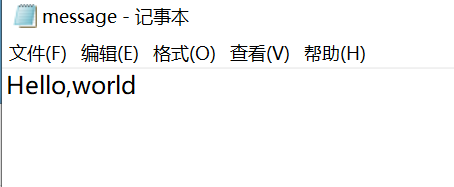

隐藏密文的大小是88


ans = 61×1 int16 列向量
    2
   -2
   -1
    2
   -1
    1
   -2
   -2
   -2
   -2


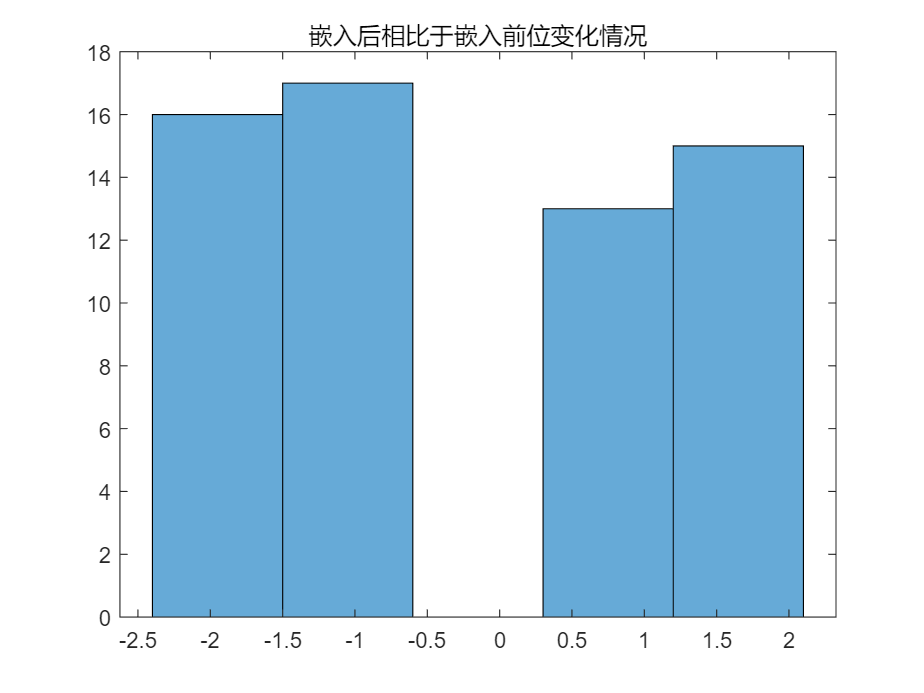

C_M=lsbRandomHide(carry,key,M,1);

保存嵌入后的图像

name2 = "image\文本嵌入后.bmp";
imwrite(C_M,name2);

使用函数lsbRead,提取消息

image_read = imread("image\文本嵌入后.bmp");
lsbRead(image_read,key,0);

得到文件的大小是88


得到的结果如下，可以看出和隐藏的信息一模一样

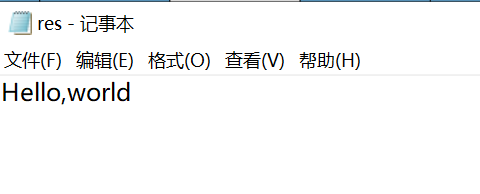

### 演示二：隐藏图片（jpg）

隐藏密文的大小是61368


ans = 30073×1 int16 列向量
    2
    2
   -1
    2
    2
   -2
    1
    2
   -1
   -2


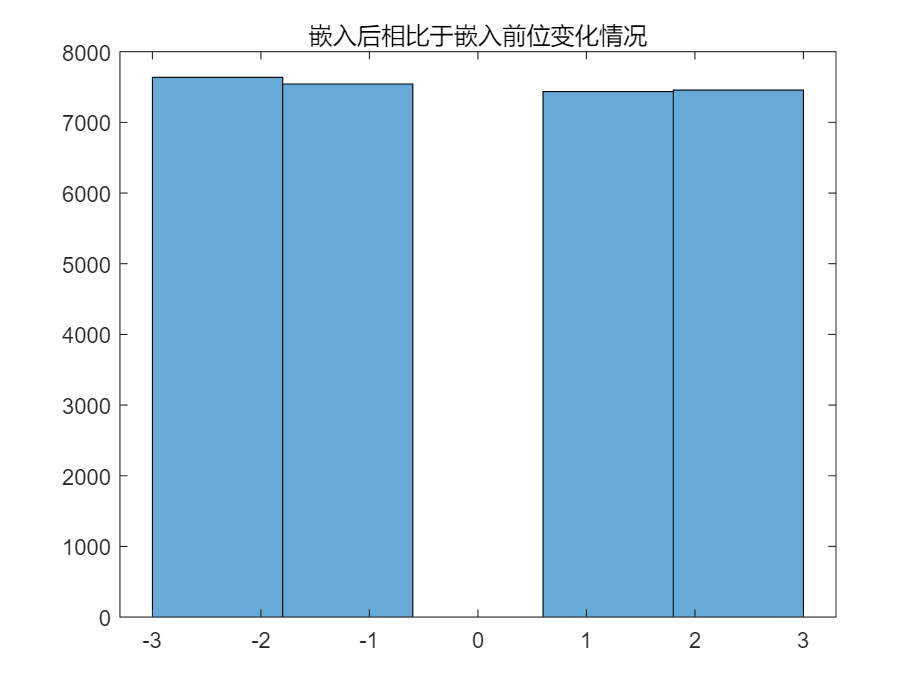

clc
clear
C='image\Lena.bmp'; % 图片路径
M='image\滑稽.jpg';
carry=imread(C);
key=1990;           % 可以随意设置
C_M=lsbRandomHide(carry,key,M,1);

name2 = "image\图片嵌入后.bmp";
imwrite(C_M,name2);

image_read = imread("image\图片嵌入后.bmp");
lsbRead(image_read,key,1);

得到文件的大小是61368


结果展示【image/res_image.jpg】：可以看到成功得到了隐藏的图片